# Глобальные переменные

clear java;
javaaddpath('/home/marina/4_curs/jeromq-0.6.0/target/jeromq-0.6.0.jar')

%addpath('/home/marina/4_curs/SimulationModel/Func'); поменять путь
global UE;
global eNB;
global frequency;
global Rays_tx;
global Rays_rx;
%global port_api = 2110;
%global pauseFlag;

UE = Subscriber(46);
eNB = BaseStation(1);
frequency = 2.3e9;
%port_api = 2110;
%pauseFlag = false;
%latitude = [];
%longitude = [];
Rays_tx = [];

# Визуализация

addpath('/home/marina/system_level_simulation/MatLab_Marina/map');

filename = '5.osm';
buildings = readgeotable(filename,Layer="buildingparts");
buildings.Shape;

Rays = [];

uniqueMaterials = unique(buildings.Material);

materials = ["","brick","concrete","glass","metal","plaster"]; 
colors = ["#c9c9c9","#870b0b","#424242","#9baceb","#543987","#ff8c90"];
dict = dictionary(materials,colors)


dict =

  dictionary (string ⟼ string) with 6 entries:

    ""         ⟼ "#c9c9c9"
    "brick"    ⟼ "#870b0b"
    "concrete" ⟼ "#424242"
    "glass"    ⟼ "#9baceb"
    "metal"    ⟼ "#543987"
    "plaster"  ⟼ "#ff8c90"




numBuildings = height(buildings);
for n = 1:numBuildings
    material = buildings.Material(n);
    buildings.Color(n) = dict(material);
end


%viewer = siteviewer(Basemap="openstreetmap",Buildings=buildings);
%viewer.Materials;
dom = xmlread(filename);

latitude = zeros(1, 2);
longitude = zeros(1, 2);

rx = rxsite("Latitude",55.010173,...%78
            "Longitude",82.947895,...%114
            "AntennaHeight",0);

% Define transmitter site at MathWorks (3 Apple Hill Dr, Natick, MA)
tx = txsite("Name", string(eNB.ID), ...
    "Latitude",55.013335, ...
    "Longitude",82.950685, ...
    "AntennaHeight",20, ...        % Units: meters
    "TransmitterFrequency",frequency, ... % Units: Hz
    "TransmitterPower",20);        % Units: Watts


pm = propagationModel("raytracing", ...
    'MaxNumReflections', 10);  % Например, 2.6 ГГц (типично для LTE)

rays_tx = raytrace(tx,rx,pm);
rays_tx = rays_tx{1};

%show(tx)
%show(rx)
%plot(rays_tx)

Rays_tx = zeros(2, length(rays_tx));
for i = 1:length(rays_tx)
    Rays_tx(1, i) = rays_tx(1, i).PhaseShift;  % Доступ через ячейку
    Rays_tx(2, i) = rays_tx(1, i).PropagationDistance;
end

disp(Rays_tx);

    5.9440    5.9456
  395.9797  395.9797



## Радиоканал

received message [184320]


received message [184320]
received message [552960]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [921600]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [552960]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received mes

received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]
received message [184320]


col = 831

received message [184320]


col = 832

received message [184320]


col = 833

received message [184320]


col = 834

received message [184320]


col = 835

received message [184320]


col = 836

received message [184320]


col = 837

received message [184320]


col = 838

received message [184320]


col = 839

received message [184320]


col = 840

received message [184320]


col = 841

received message [184320]


col = 842

received message [184320]


col = 843

received message [184320]


col = 844

received message [184320]


col = 845

received message [184320]


col = 846

received message [184320]


col = 847

received message [184320]


col = 848

received message [184320]


col = 849

received message [184320]


col = 850

received message [184320]


col = 851

received message [184320]


col = 852

received message [184320]


col = 853

received message [184320]


col = 854

received message [184320]


col = 855

received message [184320]


col = 856

received message [184320]


col = 857

received message [184320]


col = 858

received message [184320]


col = 859

received message [184320]


col = 860

received message [184320]


col = 861

received message [184320]


col = 862

received message [184320]


col = 863

received message [184320]


col = 864

received message [184320]


col = 865

received message [184320]


col = 866

received message [184320]


col = 867

received message [184320]


col = 868

received message [184320]


col = 869

received message [184320]


col = 870

received message [184320]


col = 871

received message [184320]


col = 872

received message [184320]


col = 873

received message [184320]


col = 874

received message [184320]


col = 875

received message [184320]


col = 876

received message [184320]


col = 877

received message [184320]


col = 878

received message [184320]


col = 879

received message [184320]


col = 880

received message [184320]


col = 881

received message [184320]


col = 882

received message [184320]


col = 883

received message [184320]


col = 884

received message [184320]


col = 885

received message [184320]


col = 886

received message [184320]


col = 887

received message [184320]


col = 888

received message [184320]


col = 889

received message [184320]


col = 890

received message [184320]


col = 891

received message [184320]


col = 892

received message [184320]


col = 893

received message [184320]


col = 894

received message [184320]


col = 895

received message [184320]


col = 896

received message [184320]


col = 897

received message [184320]


col = 898

received message [184320]


col = 899

received message [184320]


col = 900

received message [184320]


col = 901

received message [184320]


col = 902

received message [184320]


col = 903

received message [184320]


col = 904

received message [184320]


col = 905

received message [184320]


col = 906

received message [184320]


col = 907

received message [184320]


col = 908

received message [184320]


col = 909

received message [184320]


col = 910

received message [184320]


col = 911

received message [184320]


col = 912

received message [184320]


col = 913

received message [184320]


col = 914

received message [184320]


col = 915

received message [184320]


col = 916

received message [184320]


col = 917

received message [184320]


col = 918

received message [184320]


col = 919

received message [184320]


col = 920

received message [184320]


col = 921

received message [184320]


col = 922

received message [184320]


col = 923

received message [184320]


col = 924

received message [184320]


col = 925

received message [184320]


col = 926

received message [184320]


col = 927

received message [184320]


col = 928

received message [184320]


col = 929

received message [184320]


col = 930

received message [184320]


col = 931

received message [184320]


col = 932

received message [184320]


col = 933

received message [184320]


col = 934

received message [184320]


col = 935

received message [184320]


col = 936

received message [184320]


col = 937

received message [184320]


col = 938

received message [184320]


col = 939

received message [184320]


col = 940

received message [184320]


col = 941

received message [184320]


col = 942

received message [184320]


col = 943

received message [184320]


col = 944

received message [184320]


col = 945

received message [184320]


col = 946

received message [184320]


col = 947

received message [184320]


col = 948

received message [184320]


col = 949

received message [184320]


col = 950

received message [184320]


col = 951

received message [184320]


col = 952

received message [184320]


col = 953

received message [184320]


col = 954

received message [184320]


col = 955

received message [184320]


col = 956

received message [184320]


col = 957

received message [184320]


col = 958

received message [184320]


col = 959

received message [184320]


col = 960

received message [184320]


col = 961

received message [184320]


col = 962

received message [184320]


col = 963

received message [184320]


col = 964

received message [184320]


col = 965

received message [184320]


col = 966

received message [184320]


col = 967

received message [184320]


col = 968

received message [184320]


col = 969

received message [184320]


col = 970

received message [184320]


col = 971

received message [184320]


col = 972

received message [184320]


col = 973

received message [184320]


col = 974

received message [184320]


col = 975

received message [184320]


col = 976

received message [184320]


col = 977

received message [184320]


col = 978

received message [184320]


col = 979

received message [184320]


col = 980

received message [184320]


col = 981

received message [184320]


col = 982

received message [184320]


col = 983

received message [184320]


col = 984

received message [184320]


col = 985

received message [184320]


col = 986

received message [184320]


col = 987

received message [184320]


col = 988

received message [184320]


col = 989

received message [184320]


col = 990

received message [184320]


col = 991

received message [184320]


col = 992

received message [184320]


col = 993

received message [184320]


col = 994

received message [184320]


col = 995

received message [184320]


col = 996

received message [184320]


col = 997

received message [184320]


col = 998

received message [184320]


col = 999

received message [184320]


col = 1000

received message [184320]


col = 1001

received message [184320]


col = 1002

received message [184320]


col = 1003

received message [184320]


col = 1004

received message [184320]


col = 1005

received message [184320]


col = 1006

received message [184320]


col = 1007

received message [184320]


col = 1008

received message [184320]


col = 1009

received message [184320]


col = 1010

received message [184320]


col = 1011

received message [184320]


col = 1012

received message [184320]


col = 1013

received message [184320]


col = 1014

received message [184320]


col = 1015

received message [184320]


col = 1016

received message [184320]


col = 1017

received message [184320]


col = 1018

received message [184320]


col = 1019

received message [184320]


col = 1020

received message [184320]


col = 1021

received message [184320]


col = 1022

received message [184320]


col = 1023

received message [184320]


col = 1024

received message [184320]


col = 1025

received message [184320]


col = 1026

received message [184320]


col = 1027

received message [184320]


col = 1028

received message [184320]


col = 1029

received message [184320]


col = 1030

received message [184320]


col = 1031

received message [184320]


col = 1032

received message [184320]


col = 1033

received message [184320]


col = 1034

received message [184320]


col = 1035

received message [184320]


col = 1036

received message [184320]


col = 1037

received message [184320]


col = 1038

received message [184320]


col = 1039

received message [184320]


col = 1040

received message [184320]


col = 1041

received message [184320]


col = 1042

received message [184320]


col = 1043

received message [184320]


col = 1044

received message [184320]


col = 1045

received message [184320]


col = 1046

received message [184320]


col = 1047

received message [184320]


col = 1048

received message [184320]


col = 1049

received message [184320]


col = 1050

received message [184320]


col = 1051

received message [184320]


col = 1052

received message [184320]


col = 1053

received message [184320]


col = 1054

received message [184320]


col = 1055

received message [184320]


col = 1056

received message [184320]


col = 1057

received message [184320]


col = 1058

received message [184320]


col = 1059

received message [184320]


col = 1060

received message [184320]


col = 1061

received message [184320]


col = 1062

received message [184320]


col = 1063

received message [184320]


col = 1064

received message [184320]


col = 1065

received message [184320]


col = 1066

received message [184320]


col = 1067

received message [184320]


col = 1068

received message [184320]


col = 1069

received message [184320]


col = 1070

received message [184320]


col = 1071

received message [184320]


col = 1072

received message [184320]


col = 1073

received message [184320]


col = 1074

received message [184320]


col = 1075

received message [184320]


col = 1076

received message [184320]


col = 1077

received message [184320]


col = 1078

received message [184320]


col = 1079

received message [184320]


col = 1080

received message [184320]


col = 1081

received message [184320]


col = 1082

received message [184320]


col = 1083

received message [184320]


col = 1084

received message [184320]


col = 1085

received message [184320]


col = 1086

received message [184320]


col = 1087

received message [184320]


col = 1088

received message [184320]


col = 1089

received message [184320]


col = 1090

received message [184320]


col = 1091

received message [184320]


col = 1092

received message [184320]


col = 1093

received message [184320]


col = 1094

received message [184320]


col = 1095

received message [184320]


col = 1096

received message [184320]


col = 1097

received message [184320]


col = 1098

received message [184320]


col = 1099

received message [184320]


col = 1100

received message [184320]


col = 1101

received message [184320]


col = 1102

received message [184320]


col = 1103

received message [184320]


col = 1104

received message [184320]


col = 1105

received message [184320]


col = 1106

received message [184320]


col = 1107

received message [184320]


col = 1108

received message [184320]


col = 1109

received message [184320]


col = 1110

received message [184320]


col = 1111

received message [184320]


col = 1112

received message [184320]


col = 1113

received message [184320]


col = 1114

received message [184320]


col = 1115

received message [184320]


col = 1116

received message [184320]


col = 1117

received message [184320]


col = 1118

received message [184320]


col = 1119

received message [184320]


col = 1120

received message [184320]


col = 1121

received message [184320]


col = 1122

received message [184320]


col = 1123

received message [184320]


col = 1124

received message [184320]


col = 1125

received message [184320]


col = 1126

received message [184320]


col = 1127

received message [184320]


col = 1128

received message [184320]


col = 1129

received message [184320]


col = 1130

received message [184320]


col = 1131

received message [184320]


col = 1132

received message [184320]


col = 1133

received message [184320]


col = 1134

received message [184320]


col = 1135

received message [184320]


col = 1136

received message [184320]


col = 1137

received message [184320]


col = 1138

received message [184320]


col = 1139

received message [184320]


col = 1140

received message [184320]


col = 1141

received message [184320]


col = 1142

received message [184320]


col = 1143

received message [184320]


col = 1144

received message [184320]


col = 1145

received message [184320]


col = 1146

received message [184320]


col = 1147

received message [184320]


col = 1148

received message [184320]


col = 1149

received message [184320]


col = 1150

received message [184320]


col = 1151

received message [184320]


col = 1152

received message [184320]


col = 1153

received message [184320]


col = 1154

received message [184320]


col = 1155

received message [184320]


col = 1156

received message [184320]


col = 1157

received message [184320]


col = 1158

received message [184320]


col = 1159

received message [184320]


col = 1160

received message [184320]


col = 1161

received message [184320]


col = 1162

received message [184320]


col = 1163

received message [184320]


col = 1164

received message [184320]


col = 1165

received message [184320]


col = 1166

received message [184320]


col = 1167

received message [184320]


col = 1168

received message [184320]


col = 1169

received message [184320]


col = 1170

received message [184320]


col = 1171

received message [184320]


col = 1172

received message [184320]


col = 1173

received message [184320]


col = 1174

received message [184320]


col = 1175

received message [184320]


col = 1176

received message [184320]


col = 1177

received message [184320]


col = 1178

received message [184320]


col = 1179

received message [184320]


col = 1180

received message [184320]


col = 1181

received message [184320]


col = 1182

received message [184320]


col = 1183

received message [184320]


col = 1184

received message [184320]


col = 1185

received message [184320]


col = 1186

received message [184320]


col = 1187

received message [184320]


col = 1188

received message [184320]


col = 1189

received message [184320]


col = 1190

received message [184320]


col = 1191

received message [184320]


col = 1192

received message [184320]


col = 1193

received message [184320]


col = 1194

received message [184320]


col = 1195

received message [184320]


col = 1196

received message [184320]


col = 1197

received message [184320]


col = 1198

received message [184320]


col = 1199

received message [184320]


col = 1200

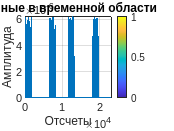

received message [184320]


col = 1201

received message [184320]


col = 1202

received message [184320]


col = 1203

received message [184320]


col = 1204

received message [184320]


col = 1205

received message [184320]


col = 1206

received message [184320]


col = 1207

received message [184320]


col = 1208

received message [184320]


col = 1209

received message [184320]


col = 1210

received message [184320]


col = 1211

received message [184320]


col = 1212

received message [184320]


col = 1213

received message [184320]


col = 1214

received message [184320]


col = 1215

received message [184320]


col = 1216

received message [184320]


col = 1217

received message [184320]


col = 1218

received message [184320]


col = 1219

received message [184320]


col = 1220

received message [184320]


col = 1221

received message [184320]


col = 1222

received message [184320]


col = 1223

received message [184320]


col = 1224

received message [184320]


col = 1225

received message [184320]


col = 1226

received message [184320]


col = 1227

received message [184320]


col = 1228

received message [184320]


col = 1229

received message [184320]


col = 1230

received message [184320]


col = 1231

received message [184320]


col = 1232

received message [184320]


col = 1233

received message [184320]


import org.zeromq.ZMQ.*;
import org.zeromq.*;
port_api = 2111;
context = ZMQ.context(1);
socket_api_proxy = context.socket(ZMQ.REP);
socket_api_proxy.bind(sprintf('tcp://*:%d', port_api));

figure(1);
global pauseFlag;
pauseFlag = false;
uicontrol('Style', 'pushbutton', 'String', 'Pause/Resume', ...
              'Position', [20, 20, 100, 30], ...
              'Callback', @(src, event) togglePause());

col = 0;

while true

    if ~pauseFlag
        msg = socket_api_proxy.recv();
        out_data = msg;
        if ~isempty(msg)
            %fprintf('received message [%d]\n', length(msg));
            %msg_port = msg(1:16);
            %msg_port = msg_port';
            %msg_port = typecast(int8(msg_port), 'uint8');
            %msg_port = typecast(msg_port, 'int16');
            %msg_port = msg_port(1:2:end);
            %disp(msg_port);
            %msg = msg(17:end);
    

            [msg_complex] = process_data(msg);

            if col > 830 %630 - 830 чистые, 830 - : испоченые
                clear msg;
                [msg_complex_rch] = RCH(msg_complex, rays_tx, tx, rx);
                %data = zeros(1, length(Srx));
                data_single = single(msg_complex_rch);
                Rpart = real(data_single);
                IMpart = imag(data_single);
                floatArray = zeros(1, 2*length(data_single));
                floatArray(1:2:end) = Rpart;
                floatArray(2:2:end) = IMpart;
                col = col
                msg = typecast(single(floatArray), 'uint8');
            end
            if mod(col, 50) == 0
                Grafic(msg)
            end

            col =col + 1; % 630 чтоб enb и ue подключились
            socket_api_proxy.send(msg);
        end
    else
        pause(0.1);
    end
end

function togglePause()
    global pauseFlag;
    pauseFlag = ~pauseFlag;
end


function Grafic(data)
    fs = 23000000;
    floatArray = typecast(uint8(data), 'single');
    complexArray = complex(floatArray(1:2:end), floatArray(2:2:end));
    data_complex = complexArray(1:128*180);
    cla;
    window = 128;    
    noverlap = 0; 
    nfft = 128;      
    if any(isnan(data_complex))
        data_complex(isnan(data_complex)) = 0;
    end
    clf;  % Очистка всей фигуры
    subplot(2, 1, 1);
    plot(real(data_complex), 'b'); hold on;
    plot(imag(data_complex), 'r');
    title('Данные во временной области (Re и Im)');
    xlabel('Отсчеты'); ylabel('Амплитуда');
    legend('Re', 'Im'); grid on;
    
    subplot(2, 1, 2);
    spectrogram(data_complex, 128, 0, 128, fs, 'yaxis');
    title('Спектрограмма'); xlabel('Время (с)'); ylabel('Частота (Гц)');
    
    drawnow limitrate;  % Оптимизация для частых обновлений
end

function [data_complex] = process_data(data_raw)
    %fprintf("size data: %d\n", length(data_raw));
    data_slice = data_raw;
    floatArray = typecast(uint8(data_slice), 'single');
    complexArray = complex(floatArray(1:2:end), floatArray(2:2:end));
    data_complex = complexArray(1:128*180);
    %fprintf("size complex data: %d\n", length(data_complex));
end

function [Srx_PL] = RCH(z, rays_tx, tx, rx)

    %z = [3 + 4i, 3 - 4i, -3 + 4i, -3 - 4i];  
    D = zeros(1, length(rays_tx));
    phase_shifts_rad = zeros(1, length(rays_tx));

    %Rays_tx = zeros(2, length(rays_tx));
    for i = 1:length(rays_tx)
        %Rays_tx(1, i) = rays_tx(1, i).PhaseShift;  % Доступ через ячейку
        phase_shifts_rad(1, i) = rays_tx(1, i).PhaseShift;
        %Rays_tx(2, i) = rays_tx(1, i).PropagationDistance;
        D(i) = rays_tx(1, i).PropagationDistance;
    end

    Nv = length(rays_tx);
    L = length(z);
    B = 9*10^6;
    Ts = 1/B;
    c = 3 * 10^8;
    t = zeros(1, Nv);
    fs = 23040000;

    [~, idx_min] = min(D);
    D = [D(idx_min) , D(1:idx_min-1), D(idx_min+1:end)];

    for i = 1:Nv
        t(i)=(D(i)-D(1))/(c*Ts);
        t(i)=round(t(i));
    end
    
    S = zeros(Nv,L+max(t));%сигнальный вектор
    Stx = z;%сигнал из передатчика
    for i = 1:Nv
        for k =  1:(L+t(i))
            if k<= t(i)
                S(i, k) = complex(0,0);
            elseif k>t(i)
                S(i, k) = Stx(k-t(i));
            end
        end
    end


    Smpy = [];%выходной сигнал

    for i = 1:Nv
        for k = 1:(L+t(i))
            Smpy(i, k) = S(i, k);
        end
    end
    Srx_tran_ch = sum(Smpy,1);

    fc = 23.04; % Частота в МГц
    hte = tx.AntennaHeight; % Высота передающей антенны в метрах
    hre = rx.AntennaHeight; % Высота приемной антенны в метрах
    d = D; % Расстояние между передатчиком и приемником в километрах 1км+ 2км+ 3км+ 5км+ 100км-
    Cm = 0; % Поправочный коэффициент для средних городов и пригородов

    % Расчет поправочного коэффициента для высоты приемной антенны
    L = [];
    
    for i = 1:Nv 
        a_hre = (1.1 * log10(fc) - 0.7) * hre - (1.56 * log10(fc) - 0.8);
        PL = 46.3 + 33.9 * log10(fc) - 13.82 * log10(hte) - a_hre + (44.9 - 6.55 * log10(hte)) * log10(d(i)) + Cm;
        for k = 1:length(Smpy)
            Smpy_L(i, k) = Smpy(i, k) * 10^(-PL / 20);  % Для комплексных чисел (I/Q);
        end
    end
    
    Srx_PL = sum(Smpy_L,1);

end